# Exemples Codis CN

### Fer una p--- taula

format longG
taula = [1 2 3; 4 5 6; 7 8 9; 0 0 0]';
T = array2table(taula,"VariableNames",{'c1','c2','c3','c4'});
disp(T)

    c1    c2    c3    c4
    __    __    __    __

    1     4     7     0 
    2     5     8     0 
    3     6     9     0 



### Arrodoniments, errors, xifres significatives i digits correctes

x = sqrt(2);
x_aprox = 1.413;
[ea,er,dc,xs] = errores(x,x_aprox)

ea =        0.00121356237309511


er =       0.000858118183408392


dc =      2


xs =      2


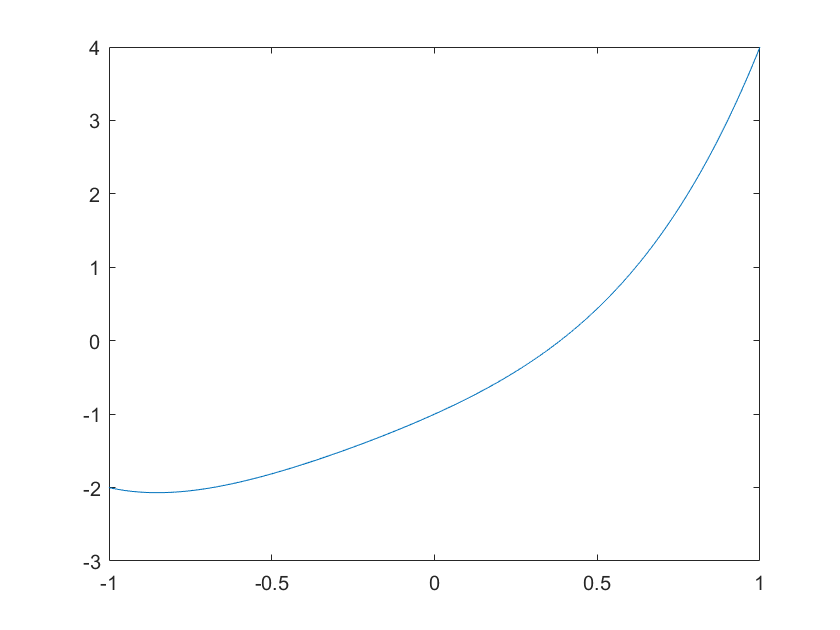


% evaluació d'un polinomi pel metode de horner en un punt(s) x = a
coeff = [1  1  1 2 -1];        % coefficients del polinomi (an... a0)
a = linspace(1,-1,200);         % punts on evaluem 
[ pa ] = horner(coeff,a);
plot(a,pa)

### Norma i nombres de condicionament

A = [1 2; 1 3];

n2=norm(A), n1 = norm(A,1); ninf=norm(A,'inf');nF=norm(A,'fro');

n2 =           3.86432845054082


condN2 = cond(A), condN1 = cond(A,1); condNf = cond(A,'fro'); condNi = cond(A,'inf');

condN2 =           14.9330343736592


% en general, sempre utilitzarem norm(A), cond(A)
% també podem saber el rank amb

rank(A)

ans =      2


### Sistemes lineals (mètodes directes)

A = [1 2; 3 1];
b = ones(2,1);
x1 = A\b

x1 =                        0.2
                       0.4


x2=linsolve(A,b);

% bs/ fs
U = [-1 2; 0 1];
x = bs(U,b)

x =      1
     1



% LU decomposition
[L,U,P]=lu(A);
% primer pas
y = fs(L,P*b);
% segon pas
x_lu = bs(U,y)

x_lu =                        0.2
                       0.4


% directament amb U\(L\P*b) 

% QR
[Q,R] = qr(A);
x_qr = bs(R,(Q'*b))

x_qr =                        0.2
                       0.4


### Sistemes lineals (mètodes iteratius)

% Metode de Jacobi
A = [1 2; 3 1];
b = ones(2,1);
D = diag(diag(A));
d = diag(1./diag(A));    %D^(-1)
L = tril(A,-1);
U = triu(A,1);

Bj = -d*(L+U), c = d*b

Bj =      0    -2
    -3     0


c =      1
     1


rhoJ = abs(eigs(Bj,1))    % no convergeix perque rhoJ > 1

rhoJ =           2.44948974278318


r = [1];
k = 0;
x = zeros(size(b));
while (r(end) > 10e-3) 
    x = Bj*x + c;
    r =[r norm(b - A*x,1)];
    k = k+1;
end
r(end), x, k

ans =    NaN


x =    Inf
   NaN


k =    795



% Metode de Gauss-Seidel
Bg = -inv(L+D)*U, cg = inv(L+D)*b

Bg =      0    -2
     0     6


cg =      1
    -2


rhoG = abs(eigs(Bg,1))      % no convergeix perque rhoG > 1 (dubte)

rhoG =      6



r = [1];
k = 0;
x = zeros(size(b));
%while (k < 10)
while (r(end) > 10e-6) 
    x = Bg*x + cg;
    r =[r norm(b - A*x,1)];
    k = k+1;
end
r(end), x, k

ans =    NaN


x =      1.12456649186535e+308
                      -Inf


k =    397


### Inversa d'una matriu per LU

% resoldrem columna a columna
A = [1 2; 3 1];
[L,U,P]=lu(A);
B=eye(size(A));

% primera columna de inversa(A)
b = B(:,1);
x1 = U\(L\P*b);
% segona columna de inversa(A)
b = B(:,2);
x2 = U\(L\P*b);

% resultat/ verificacio
iA=[x1,x2]

iA =                       -0.2                       0.4
                       0.6                      -0.2


% I = iA*A

#### Vectors i valors propis (vaps i veps)

A = [1 2; 1 3];
[V,D]=eig(A);           % Matriu de vectors propis, matriu de valors propis
vaps = diag(D)         % vectors de vaps

vaps =          0.267949192431123
          3.73205080756888


veps = V

veps =         -0.939070801588044        -0.590690494568872
          0.34372376933344        -0.806898221355073


d = det(A-eye(2)*vaps(1))  % comprovacio que vap1 es vap

d =      -3.47625514608047e-16



rho = abs(eigs(A,1));   % radi = vap de mòdul màxim --> rho(A) <||A||

% Calcul de vaps amb polinomi caracteristic
vaps = roots(poly(A))       % poly(A) retorna el polinomic caracteristic de A

vaps =           3.73205080756888
         0.267949192431123



% Metode de la potencia per a calcul de vap de modul maxim (i vep associat)
x = [1, 1]';

k = 0;
tol = 1;
while (tol > eps) 
    z = A*x;
    m = norm(z, 'inf');
    tmp = 1/m * z;
    tol = norm(tmp-x, 'inf');
    x = tmp;
    k = k + 1;
end
m   %aproximacio del valor propi

m =           3.73205080756888


x   % aproximacio del vector propi

x =          0.732050807568877
                         1


%residu = norm((A-m*eye(2))*x,'inf') ; 

% Metode de la potencia per a calcul de vap de modul minim
[L, U, P] = lu(A);

k = 0;
tol = 1;
while (tol > 0.5e-4) 
    % z = iA*x; --> ineficient perque cal calcular A^(-1)

    z = U\(L\P*x);    %resolucio del sistema lineal A*z = x
    [~,j] = max(abs(z));
    m = z(j);
    tmp = 1/m * z;
    tol = norm(tmp-x, 'inf')/norm(tmp,'inf');   %error relatiu aproximat
    x = tmp;
    k = k + 1;
end
1/m     % el vap de la matriu original es llavors 1/m

ans =           3.73205080756888


### Coses de polinomis

% Friendly reminder de que evaluis amb polyval
p = [1 0 0 0 0 -1];             % vector amb els coeficients del polinomi 
x = linspace(-1,1,200);         % malla per evaluar
y = polyval(p,x)                % valor polinomi en la malla x

y =    -2.0000   -1.9507   -1.9035   -1.8581   -1.8145   -1.7728   -1.7327   -1.6944   -1.6576   -1.6225   -1.5888   -1.5567   -1.5259   -1.4966   -1.4685   -1.4417   -1.4162   -1.3919   -1.3687   -1.3466   -1.3256   -1.3057   -1.2867   -1.2687   -1.2515   -1.2353   -1.2199   -1.2054   -1.1916   -1.1786   -1.1663   -1.1546   -1.1437   -1.1333   -1.1236   -1.1145   -1.1059   -1.0978   -1.0902   -1.0831   -1.0765   -1.0703   -1.0645   -1.0590   -1.0540   -1.0493   -1.0449   -1.0409   -1.0371   -1.0337



% Donades unes arrels r, contrueix el polinomi
r = [-1 1];
p = poly(r) 

p =      1     0    -1



% un polinomi random
arrels = [6 5 3 -2 -1];
f = poly(arrels);
x = linspace(-2.5,6.5,500);
plot(x, polyval(f,x))
grid on;

### Polinomi interpolador (matriu de Vandermonde)

x = [0,1,2,3];
y = [-5 -6 -1 16];
u = linspace(0,3,500)
fu = polyinterp(x,y,u) % polinomi interpolador de x i y evaluat en u


### Least Squares polynomial fitting (with Vandermonde)

f = @(x)  x.^2 -2        % the function to interpolate
n = 25;                  % the number of points to do the interpolation
m = 10;                   % the degree of the interpoland

% Create n nodes
jj = 0:n;
xj = -1+2*jj/n;         %equispaced
% xj = cos(jj*pi/n);    %Chebyshev
 
% Create the vandermonde matrix of the equispaced nodes
V = fliplr(vander(xj));
V = V(:, 1:m+1);

% Solve the system to find the a_i coefficients of the polynomial interpolation 
fx = f(xj)';
UR = myqr(V);
a = qrsolve(UR,fx);

% Create the Vandermonde matrix for a mesh to evaluate the polynomial
mesh = linspace(-2,2,500);
X = fliplr(vander(mesh));
X = X(:, 1:m+1);

% Plot f(x) vs the polynomical approximation    
figure(1)
title('Least Squares Polynomial Fit', 'Interpreter', 'latex')
subtitle('With equispaced nodes', 'Interpreter', 'latex')
xlabel('$x$', 'Interpreter', 'latex')
ylabel('$f(x)$', 'Interpreter', 'latex')
plot(mesh, X*a, 'Linewidth',0.8)   